# Furuta Pendulum - Mathematical Model

## 1. Physical Parameters

Load the CAD parameters already converted to SI units. Mass is in kg, length is in m, and inertia is in kg m^2. The long CAD import code does not need to run again.

assert(isfolder('data') && isfolder('models'),'Set Current Folder to Furuta_Clean_Project.');
addpath('models','geometry');
load('data/Physical_Parameters.mat');
mass_table = table(m_arm,m_pend)

mass_table = 1×2 table
     m_arm      m_pend  
    _______    _________

    0.18332    0.0072213


D_mech

D_mech = 1.0e-03 *

    0.5730         0
         0    0.0315


% c_arm, c_pend: COM vectors measured from their joint frames.
% d_pivot: vector from motor joint to pendulum joint.
% I_arm, I_pend: COM inertia tensors expressed in joint frames.


## 2. Coordinates

theta is the arm angle. alpha is the pendulum angle measured from upright. The negative rotation sign follows the CAD joint directions. It does not change the physical model.

syms theta alpha theta_dot alpha_dot real
q = [theta; alpha];
qd = [theta_dot; alpha_dot];
Rz = @(a) [cos(a),sin(a),0; -sin(a),cos(a),0; 0,0,1];
R0 = Rz(theta);
R1 = Rz(alpha + q_offset);
ez = [0;0;1];


## 3. Position and Velocity

Find the center-of-mass position of each body. Differentiate position to get velocity. R_world_motor and R_arm_pend describe the frame directions from CAD.

p_arm = R_world_motor*R0*c_arm;
p_pend = R_world_motor*R0*(d_pivot + R_arm_pend*R1*c_pend);
v_arm = jacobian(p_arm,q)*qd;
v_pend = jacobian(p_pend,q)*qd;
w_arm = -R_world_motor*ez*theta_dot;
w_pend = R_world_motor*(-ez*theta_dot - R0*R_arm_pend*ez*alpha_dot);
I_arm_world = R_world_motor*R0*I_arm*R0'*R_world_motor';
Rp = R_world_motor*R0*R_arm_pend*R1;
I_pend_world = Rp*I_pend*Rp';


## 4. Kinetic and Potential Energy

T is the total kinetic energy from translation and rotation. V is gravitational potential energy. Removing a fixed origin offset does not change the equations of motion.

T_sym = 0.5*m_arm*(v_arm'*v_arm) + 0.5*w_arm'*I_arm_world*w_arm ...
      + 0.5*m_pend*(v_pend'*v_pend) + 0.5*w_pend'*I_pend_world*w_pend;
V_sym = -m_arm*g'*p_arm - m_pend*g'*p_pend;
T_sym = simplify(vpa(T_sym,15),'Steps',5);
V_sym = simplify(vpa(V_sym,15),'Steps',5);


## 5. Nonlinear Equations

Use Euler-Lagrange: M(q) qdd + h(q,qd) + G(q) + D qd = [tau;0]. The state is x = [theta;alpha;theta_dot;alpha_dot]. The full derivation is shown here without an external helper.

momentum = jacobian(T_sym,qd).';
M_sym = simplify(jacobian(momentum,qd),'Steps',5);
h_sym = simplify(jacobian(momentum,q)*qd - jacobian(T_sym,q).','Steps',5);
G_sym = simplify(jacobian(V_sym,q).','Steps',5);
M_fun = matlabFunction(M_sym,'Vars',{q},'Optimize',false);
h_fun = matlabFunction(h_sym,'Vars',{q,qd},'Optimize',false);
G_fun = matlabFunction(G_sym,'Vars',{q},'Optimize',false);
f = @(x,tau) [x(3:4); M_fun(x(1:2))\([tau;0] ...
    - h_fun(x(1:2),x(3:4)) - G_fun(x(1:2)) - D_mech*x(3:4))];
M_at_upright = M_fun([0;0])

M_at_upright = 1.0e-03 *

    0.1553   -0.0082
   -0.0082    0.0116


save('data/Nonlinear_Model.mat','q','qd','M_sym','h_sym','G_sym', ...
    'D_mech','M_fun','h_fun','G_fun');


## 6. Open-Loop Validation

Run Simscape without a controller. Then solve our equations with ode45 from the same initial state. Split the time interval at the pulse edges so the solver applies the pulse correctly.

model = 'Furuta_Validation_Study1';
load_system(fullfile(pwd,'models',[model '.slx']));
in = Simulink.SimulationInput(model);
in = in.setModelParameter('StopTime','0.5');
in = in.setBlockParameter([model '/Torque command Nm'],'Value','0');
in = in.setBlockParameter([model '/Pulse starts'],'Time','0.10');
in = in.setBlockParameter([model '/Pulse starts'],'After','0.001');
in = in.setBlockParameter([model '/Pulse ends'],'Time','0.12');
in = in.setBlockParameter([model '/Pulse ends'],'After','-0.001');
run_validation = sim(in);
xs = run_validation.x_simscape;
x0 = xs.Data(1,:)';
edges = [0,0.10,0.12,0.50]; torque = [0,0.001,0];
ta = 0; xa = x0'; options = odeset('RelTol',1e-9,'AbsTol',1e-11);
for k = 1:3
    [tk,xk] = ode45(@(time,x) f(x,torque(k)),edges(k:k+1),x0,options);
    ta = [ta;tk(2:end)]; xa = [xa;xk(2:end,:)];
    x0 = xk(end,:)';
end


## 7. Validation Results

Compare all four states. Calculate the maximum error and RMS error. This checks agreement for one test. It does not measure the hardware parameters.

t = (0:0.001:0.5)';
[ts,index] = unique(xs.Time);
x_simscape = interp1(ts,xs.Data(index,:),t,'pchip');
x_analytical = interp1(ta,xa,t,'pchip');
error_states = x_analytical - x_simscape;
State = ["Arm angle";"Pendulum angle";"Arm velocity";"Pendulum velocity"];
MaxError = max(abs(error_states),[],1)';
RMSError = sqrt(mean(error_states.^2,1))';
validation_table = table(State,MaxError,RMSError)

validation_table = 4×3 table
           State            MaxError      RMSError 
    ___________________    __________    __________

    "Arm angle"            6.7954e-08    3.6283e-09
    "Pendulum angle"       5.1418e-07    2.4635e-08
    "Arm velocity"         2.5618e-07    1.6021e-08
    "Pendulum velocity"    5.3193e-06    2.6127e-07


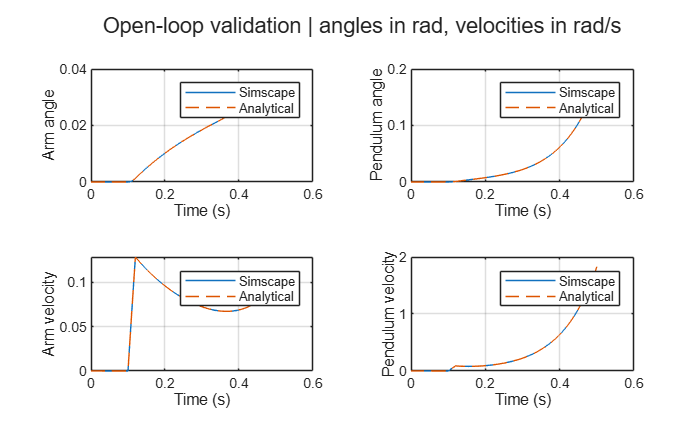

figure('Name','Nonlinear model validation','Color','w'); tiledlayout(2,2);
for k = 1:4
    nexttile; plot(t,x_simscape(:,k),t,x_analytical(:,k),'--'); grid on;
    xlabel('Time (s)'); ylabel(State(k)); legend('Simscape','Analytical');
end
sgtitle('Open-loop validation | angles in rad, velocities in rad/s');
drawnow; exportgraphics(gcf,'results/Model_Validation.png','Resolution',140);

save('results/Model_Validation.mat','t','x_simscape','x_analytical','validation_table');
